# Tarea 4: Profesor Laboret

Para la tarea se elige la primer fila de la tabla de los valores de masa, longitud, coeficiente de rozamiento y ángulo de referencia en grados del sistema péndulo simple.

clear all; close all; clc

Se comienza definiendo los parámetros a utilizar.

m = 3

m = 3

b = 0.1

b = 0.1000

delta = 135

delta = 135

l = 1;
G = 10;

Se obtiene el modelo en espacio de estado para el sistema del péndulo linealizado a partir del modelo de Simulink.

[A,B,C,D] = linmod('pendulo_mod_tarea',delta*pi/180)

A =          0    1.0000
    7.0711   -0.0333


B =          0
    0.3333


C =      1     0


D = 0

Los autovalores de la matriz A, que son los polos del sistema, son:

eig(A)

ans =     2.6425
   -2.6759


El rango  de la matriz de controlabilidad es el siguiente:

rank(ctrb(A,B))

ans = 2

Se amplían las matrices, de modo de obtener la acción integral del controlador.

Aa = [[A;C] zeros(3,1)]

Aa =          0    1.0000         0
    7.0711   -0.0333         0
    1.0000         0         0


Ba = [B;0]

Ba =          0
    0.3333
         0


eig(Aa)

ans =          0
   -2.6759
    2.6425


rank(ctrb(Aa,Ba))

ans = 3

ctrb(Aa,Ba)

ans =          0    0.3333   -0.0111
    0.3333   -0.0111    2.3574
         0         0    0.3333


Polo triple en -4.

p = -4

p = -4

K = acker(Aa,Ba,[p p p])

K =   165.2132   35.9000  192.0000


k1 = K(1)

k1 = 165.2132

k2 = K(2)

k2 = 35.9000

k3 = K(3)

k3 = 192

eig(Aa-Ba*K) 

ans =   -4.0000 + 0.0000i
  -4.0000 + 0.0000i
  -4.0000 - 0.0000i


tscalc = 7.5/(-p) 

tscalc = 1.8750

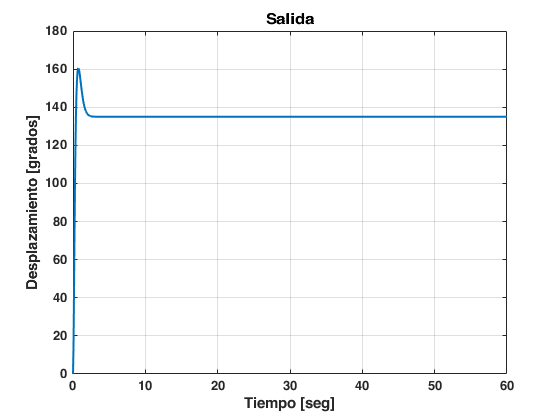

sim('pendulo_pid_tarea')
ym1 = yout;
vel1 = velocidad;
tor1 = torque;
int1 = accint;
plot(tout,yout, 'LineWidth',1.5)
grid on
title('Salida')
xlabel('Tiempo [seg]'); 
ylabel('Desplazamiento [grados]')

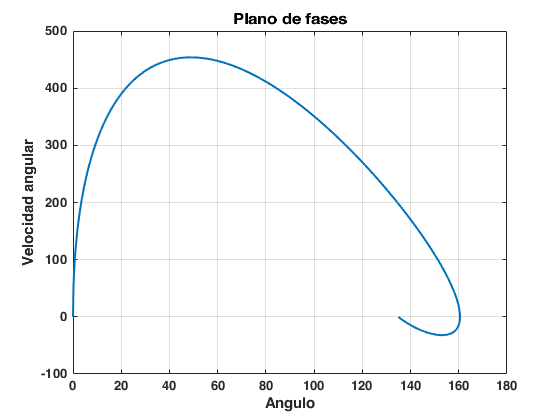

plot(yout,velocidad, 'LineWidth',1.5) 
grid 
title('Plano de fases');
xlabel('Angulo'); 
ylabel('Velocidad angular')

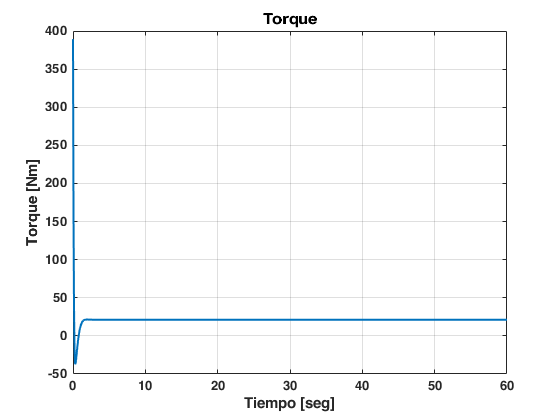

plot(tout,torque, 'LineWidth',1.5) 
grid on, 
title('Torque'); 
xlabel('Tiempo [seg]'); 
ylabel('Torque [Nm]')

plot(tout,-accint, 'LineWidth',1.5) 
grid  
title('Accion integral'); 
xlabel('Tiempo [seg]'); 
ymax = max(yout) 

ymax = 160.5228

S = (ymax-delta)/delta*100 

S = 18.9058

erel = (delta-yout)/delta; 
efinal = erel(end)

efinal = 2.8843e-14

ind = find(abs(erel)>.02); 
tss = tout(ind(end)) 

tss = 1.8043

yte = yout(ind(end)) 

yte = 137.7007

uf = torque(end) 

uf = 21.2132

Intf = -accint(end) 

Intf = 21.2132

Para probar la robustez del controlador, se simulará con variaciones de 10% en el valor de masa.

m = 3*1.1

m = 3.3000

b = 0.1

b = 0.1000

delta = 135

delta = 135

l = 1;
G = 10;
[A,B,C,D] = linmod('pendulo_mod_tarea',delta*pi/180)

A =          0    1.0000
    7.0711   -0.0303


B =          0
    0.3030


C =      1     0


D = 0

eig(A)

ans =     2.6440
   -2.6743


rank(ctrb(A,B))

ans = 2

Aa = [[A;C] zeros(3,1)]

Aa =          0    1.0000         0
    7.0711   -0.0303         0
    1.0000         0         0


Ba = [B;0]

Ba =          0
    0.3030
         0


eig(Aa)

ans =          0
   -2.6743
    2.6440


rank(ctrb(Aa,Ba))

ans = 3

p = -4

p = -4

K = acker(Aa,Ba,[p p p])

K =   181.7345   39.5000  211.2000


k1 = K(1)

k1 = 181.7345

k2 = K(2)

k2 = 39.5000

k3 = K(3)

k3 = 211.2000

eig(Aa-Ba*K) 

ans =   -4.0000 + 0.0000i
  -4.0000 - 0.0000i
  -3.9999 + 0.0000i


tscalc = 7.5/(-p) 

tscalc = 1.8750

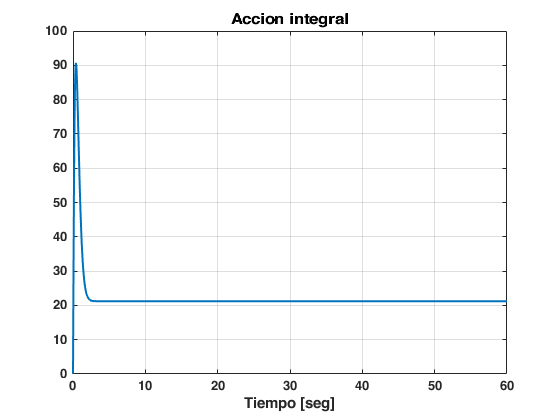

sim('pendulo_pid_tarea')

ym2 = yout;
vel2 = velocidad;
tor2 = torque;
int2 = accint;
plot(tout,yout, 'LineWidth',1.5)
grid on
title('Salida')
xlabel('Tiempo [seg]'); 
ylabel('Desplazamiento [grados]')

plot(yout,velocidad, 'LineWidth',1.5) 
grid 
title('Plano de fases');
xlabel('Angulo'); 
ylabel('Velocidad angular')

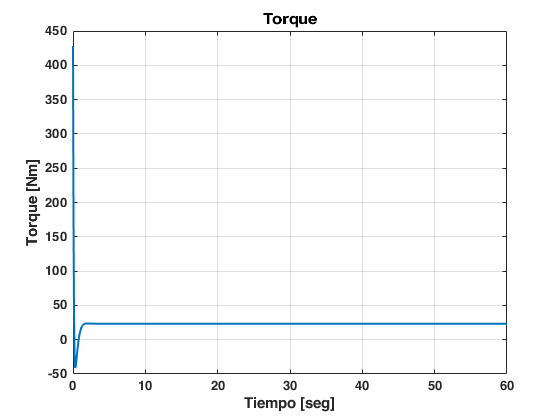

plot(tout,torque, 'LineWidth',1.5) 
grid on, 
title('Torque'); 
xlabel('Tiempo [seg]'); 
ylabel('Torque [Nm]')

plot(tout,-accint, 'LineWidth',1.5) 
grid  
title('Accion integral'); 
xlabel('Tiempo [seg]'); 
ymax = max(yout) 

ymax = 160.5228

S = (ymax-delta)/delta*100 

S = 18.9058

erel = (delta-yout)/delta; 
efinal = erel(end)

efinal = 2.9474e-14

ind = find(abs(erel)>.02); 
tss = tout(ind(end)) 

tss = 1.8043

yte = yout(ind(end)) 

yte = 137.7007

uf = torque(end) 

uf = 23.3345

Intf = -accint(end)

Intf = 23.3345

m = 3*0.9

m = 2.7000

b = 0.1

b = 0.1000

delta = 135

delta = 135

l = 1;
G = 10;
[A,B,C,D] = linmod('pendulo_mod_tarea',delta*pi/180)

A =          0    1.0000
    7.0711   -0.0370


B =          0
    0.3704


C =      1     0


D = 0

eig(A)

ans =     2.6407
   -2.6777


rank(ctrb(A,B))

ans = 2

Aa = [[A;C] zeros(3,1)]

Aa =          0    1.0000         0
    7.0711   -0.0370         0
    1.0000         0         0


Ba = [B;0]

Ba =          0
    0.3704
         0


eig(Aa)

ans =          0
   -2.6777
    2.6407


rank(ctrb(Aa,Ba))

ans = 3

p = -4

p = -4

K = acker(Aa,Ba,[p p p])

K =   148.6919   32.3000  172.8000


k1 = K(1)

k1 = 148.6919

k2 = K(2)

k2 = 32.3000

k3 = K(3)

k3 = 172.8000

eig(Aa-Ba*K) 

ans =   -4.0000 + 0.0000i
  -4.0000 + 0.0000i
  -4.0000 - 0.0000i


tscalc = 7.5/(-p) 

tscalc = 1.8750

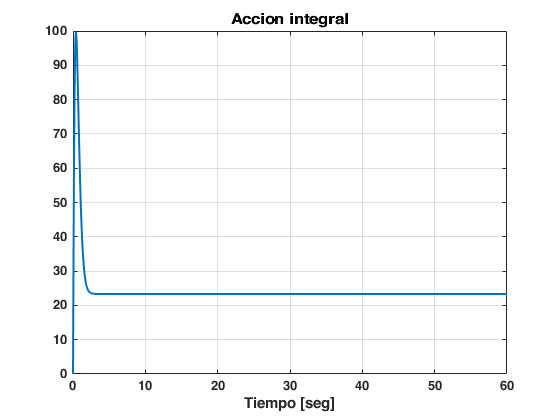

sim('pendulo_pid_tarea')

ym3 = yout;
vel3 = velocidad;
tor3 = torque;
int3 = accint;
plot(tout,yout, 'LineWidth',1.5)
grid on
title('Salida')
xlabel('Tiempo [seg]'); 
ylabel('Desplazamiento [grados]')

plot(yout,velocidad, 'LineWidth',1.5) 
grid 
title('Plano de fases');
xlabel('Angulo'); 
ylabel('Velocidad angular')

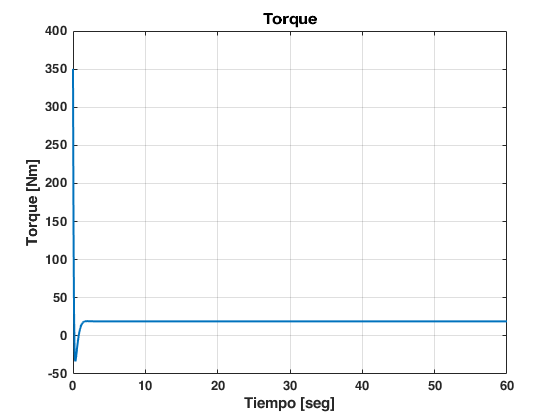

plot(tout,torque, 'LineWidth',1.5) 
grid on, 
title('Torque'); 
xlabel('Tiempo [seg]'); 
ylabel('Torque [Nm]')

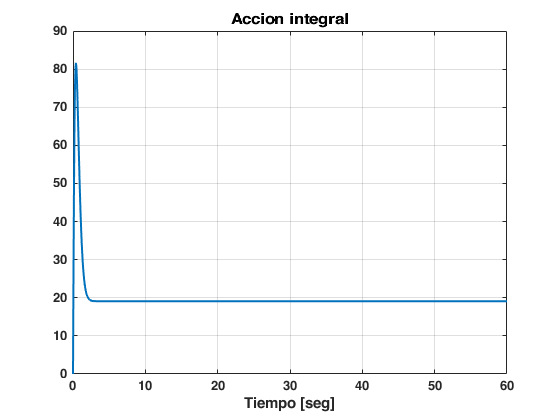

plot(tout,-accint, 'LineWidth',1.5) 
grid  
title('Accion integral'); 
xlabel('Tiempo [seg]'); 

ymax = max(yout) 

ymax = 160.5228

S = (ymax-delta)/delta*100 

S = 18.9058

erel = (delta-yout)/delta; 
efinal = erel(end)

efinal = 2.9053e-14

ind = find(abs(erel)>.02); 
tss = tout(ind(end)) 

tss = 1.8043

yte = yout(ind(end)) 

yte = 137.7007

uf = torque(end) 

uf = 19.0919

Intf = -accint(end)

Intf = 19.0919

Se comparan las señales obtenidas:

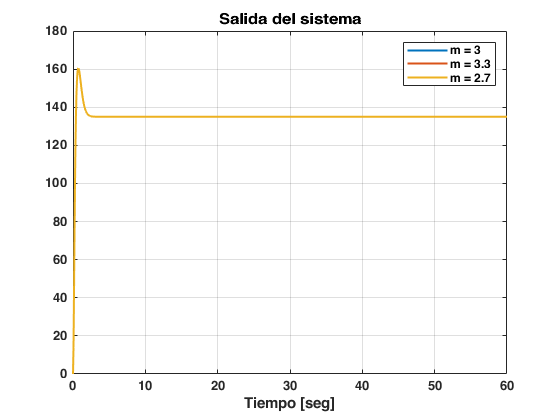

plot(tout,ym1,"LineWidth",1.5)
hold on;
plot(tout,ym2,"LineWidth",1.5)
plot(tout,ym3,"LineWidth",1.5)
grid;
hold off;
title('Salida del sistema')
xlabel('Tiempo [seg]')
legend('m = 3','m = 3.3','m = 2.7')

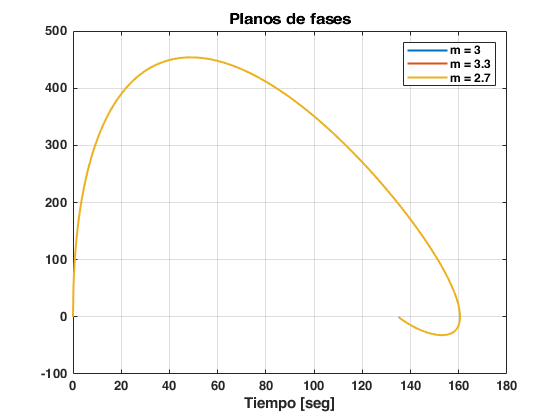

plot(ym1,vel1,"LineWidth",1.5)
hold on;
plot(ym2,vel2,"LineWidth",1.5)
plot(ym2,vel2,"LineWidth",1.5)
grid;
hold off;
title('Planos de fases')
xlabel('Tiempo [seg]')
legend('m = 3','m = 3.3','m = 2.7')

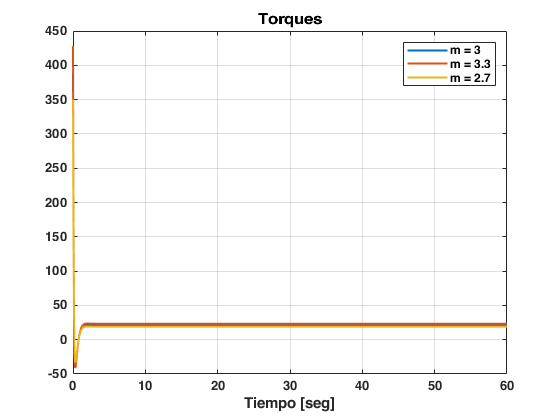

plot(tout,tor1,"LineWidth",1.5)
hold on;
plot(tout,tor2,"LineWidth",1.5)
plot(tout,tor3,"LineWidth",1.5)
grid;
hold off;
title('Torques')
xlabel('Tiempo [seg]')
legend('m = 3','m = 3.3','m = 2.7')

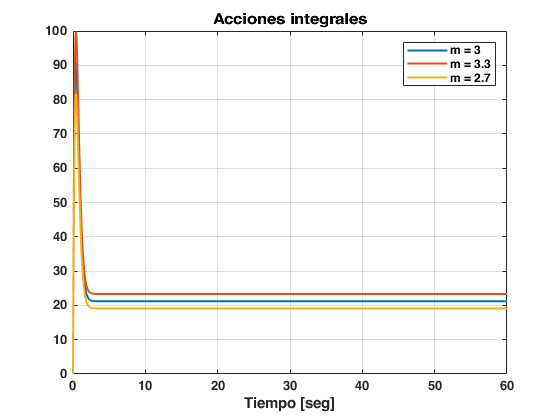

plot(tout,-int1,"LineWidth",1.5)
hold on;
plot(tout,-int2,"LineWidth",1.5)
plot(tout,-int3,"LineWidth",1.5)
grid;
hold off;
title('Acciones integrales')
xlabel('Tiempo [seg]')
legend('m = 3','m = 3.3','m = 2.7')